clear all
close all
set(gcf,'Visible','on')
syms m p w0

f = logspace(1,5,1000);
w0 = 2*pi*1e3;
m = [0.05:0.05:1/sqrt(2)]';

p = 1i*2*pi.*f;

H = 1./(1+2*m*(p/w0)+(p.^2/w0^2))

H =    1.0001 - 0.0010i   1.0001 - 0.0010i   1.0001 - 0.0010i   1.0001 - 0.0010i   1.0001 - 0.0010i   1.0001 - 0.0010i   1.0001 - 0.0011i   1.0001 - 0.0011i   1.0001 - 0.0011i   1.0001 - 0.0011i   1.0001 - 0.0011i   1.0001 - 0.0011i   1.0001 - 0.0011i   1.0001 - 0.0011i   1.0001 - 0.0011i   1.0001 - 0.0011i   1.0001 - 0.0012i   1.0001 - 0.0012i   1.0001 - 0.0012i   1.0001 - 0.0012i   1.0001 - 0.0012i   1.0001 - 0.0012i   1.0001 - 0.0012i   1.0002 - 0.0012i   1.0002 - 0.0012i   1.0002 - 0.0013i   1.0002 - 0.0013i   1.0002 - 0.0013i   1.0002 - 0.0013i   1.0002 - 0.0013i   1.0002 - 0.0013i   1.0002 - 0.0013i   1.0002 - 0.0013i   1.0002 - 0.0014i   1.0002 - 0.0014i   1.0002 - 0.0014i   1.0002 - 0.0014i   1.0002 - 0.0014i   1.0002 - 0.0014i   1.0002 - 0.0014i   1.0002 - 0.0014i   1.0002 - 0.0015i   1.0002 - 0.0015i   1.0002 - 0.0015i   1.0002 - 0.0015i   1.0002 - 0.0015i   1.0002 - 0.0015i   1.0002 - 0.0015i   1.0002 - 0.0016i   1.0002 - 0.0016i
   1.0001 - 0.0020i   1.0001 - 0.0020i   1.00


QdB = 0*m  % Q en décibel

QdB =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fr = 0*m  % Fréquence de résonnance

fr =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for k=1:1:length(m)
   H = subs(H);
   [M,I] = max(20 .* log10(abs(H(k,:))));
   QdB(k) = M;
   fr(k) = f(I); % On a la fréquence fr à I de la fréquence
end
z = ((2*pi*fr)/w0).^2

z =     0.9908
    0.9727
    0.9549
    0.9204
    0.8708
    0.8240
    0.7514
    0.6852
    0.5913
    0.5008


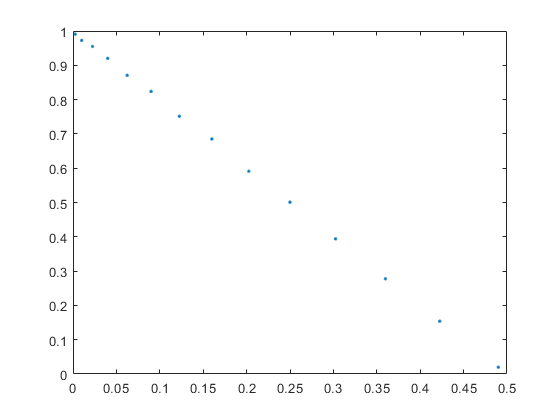

figure
plot(m.^2,z,'.');

% fr = (w0/2pi)sqrt(-2m²)
p = polyfit(m.^2,z,1)

p =    -1.9961    0.9981


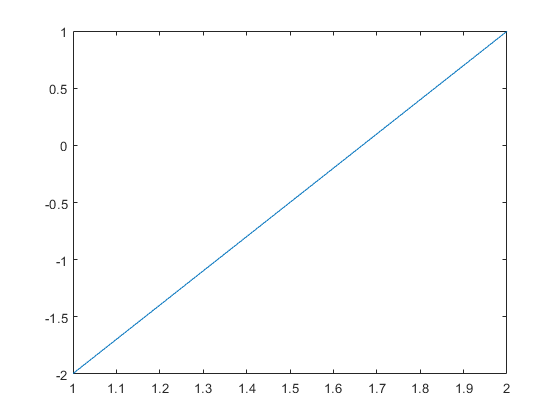

plot(p);


Q = 10.^(QdB/20)

Q =    10.0038
    5.0218
    3.3715
    2.5516
    2.0655
    1.7471
    1.5250
    1.3638
    1.2442
    1.1547


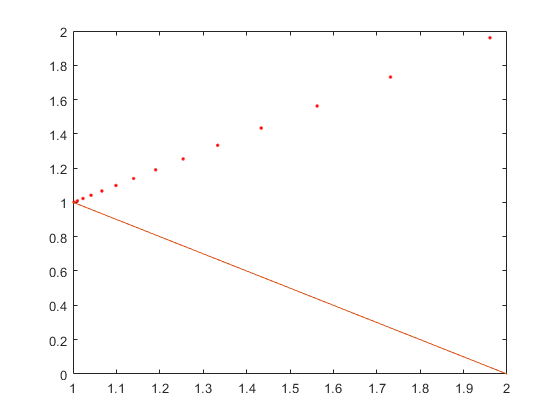

plot(1./(1-m.^2),(2*Q.*m).^2,'.r');
hold on
q = polyfit(1./(1-m.^2),(2*Q.*m).^2,1);
plot(q);

% 2mQ² = 1*(1/1-m²)+0;
% 
% Passage en Db : 20logQ -> QdB